clc
clear all
close all

x1 = [106 160 180 197.7 217.7 320]; 
x2 = [517 1017 1517 2017 3017 4017 5017 6017 7017];
y1 = [88 648 688 704 720 736];
y2 = [736 744 752 768 776 784 792 800 808];
plot(x1,y1)
xlabel('Weight (g)');
ylabel('Voltage (mV)');

c1 = polyfit(x1,y1,1);

disp(['Equation: ' num2str(c1(1)) '*x + ' num2str(c1(2))])

Equation: 2.4553*x + 113.88


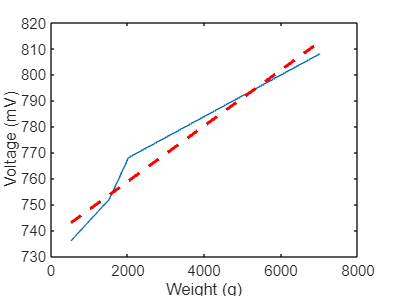

y_est = polyval(c1,x1);
hold on
plot(x1,y_est, 'r--', 'LineWidth', 2)
hold off